# Dataset Information

The dataset was downloaded from "https://www.eia.gov/electricity/data.php#netmetering" and contains multiple sheets with state-wise and country-wide data of power consumption in the United States from January 2010 to November 2023. The data is divided into Residential, Commercial, Industrial and Total sections. Each of these sections have Revenue(Thousand dollars), Sales(MWh), Customers(Number of customers) and Price(Cents/KWh) columns. 

The important thing to note here is that the dataset does not have any missing values. In the following sections we will be using the country-wide monthly total consumption data for the time series decomposition and forecasting tasks.

#### Time Format Correction

The time information in the dataset is represented by two columns: Year and Months. In order to make plotting data against time easier, in this section the columns "Month" and "Year" are being replaced by a column named "DateTime", which is in MATLAB's datetime format. As we are dealing with month-wise consumption data, the new time column represents the last date of each corresponding month.

Start_time = datetime(2010,1:12,1);
End_time = datetime(2023,11,1);
Date_time = datetime(USConsumptionData.Year,USConsumptionData.Month,1);
Date_time = dateshift(Date_time,'end','month');
data_being_processed = removevars(USConsumptionData,["Month" "Year"]);
data_being_processed = addvars(data_being_processed,Date_time,'NewVariableNames',"DateTime", 'Before',"RES_Revenue_Thousand_Dollars");
actual_time_series = data_being_processed.TOTAL_Consumption_MWh;

# Time Series Decomposition

## Discovering the Trend

Upon plotting the consumption data, it is noticeable that the consumption has slightly increased over the years. This can be represented by a small upwards trend in the time series. To better visualize the trend the following section applies smoothing to the data and then plots it over the raw consumption data. 

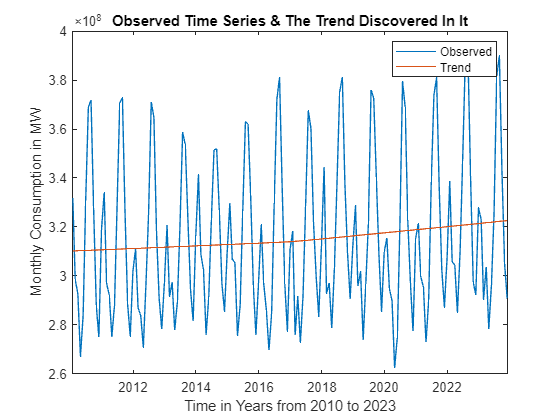

plot(Date_time,actual_time_series)
trend = smoothdata(actual_time_series, "lowess","SmoothingFactor",1); % Applying smoothing to discover the presence of trend
hold on
plot(Date_time, trend)
hold off
xlabel("Time in Years from 2010 to 2023")
ylabel("Monthly Consumption in MW")
title("Observed Time Series & The Trend Discovered In It")
legend("Observed", "Trend")

## Calculating Seasonal Component

As the follow-on step to removing the identified trend from the time series, the calculation of seasonal component is done first by using the knowledge of the dataset as well as visually checking the plot. Since the time series contains monthly observations, it is easy to reach the conclusion that the periodicity of the seasonal component is 12 months. The calculation of seasonal component is done by averaging the values of each month for all the years. For example, all entries corresponding to the January months, i.e., Jan 2010, Jan 2011, etc., are used to calculate the value of the first month of the seasonal component. The seasonal component contains values for all 12 months, but as our data spans over almost 14 years the seasonal component is repeated for the entire duration of the time series to get the complete seasonal component.         

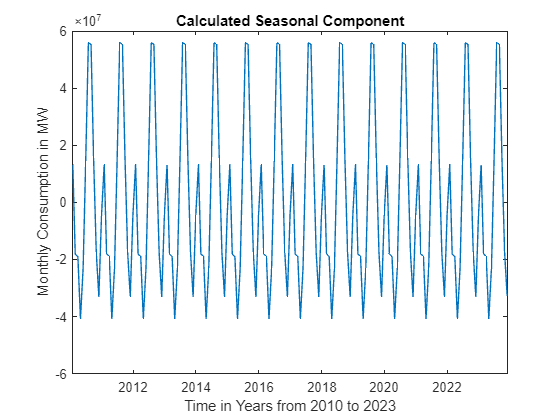

de_trend_using_smoothing = USConsumptionData.TOTAL_Consumption_MWh - trend;
seasonality_period = 12;
sidx = cell(seasonality_period,1);
for i = 1:seasonality_period
 sidx{i,1} = i:seasonality_period:(12*(2023-2010)); 
end
seasonality_component_for_seasonality_period = cellfun(@(x) mean(de_trend_using_smoothing(x)),sidx);
complete_years = floor(size(data_being_processed,1)/seasonality_period);    % Num. complete years
extra_months = mod(size(data_being_processed,1),seasonality_period);      % Num. extra months
seasonality_component_complete = [repmat(seasonality_component_for_seasonality_period,complete_years,1);seasonality_component_for_seasonality_period(1:extra_months)];
plot(Date_time,seasonality_component_complete)
xlabel("Time in Years from 2010 to 2023")
ylabel("Monthly Consumption in MW")
title("Calculated Seasonal Component")

## Residual

Once the complete seasonal component is available, the residual can be obtained by subtracting it from the detrended time series. 

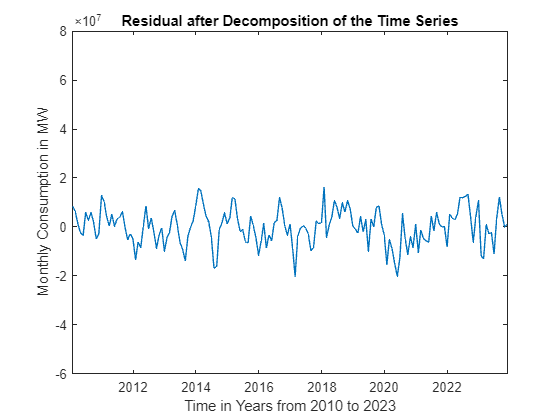

residual = de_trend_using_smoothing-seasonality_component_complete;
plot(Date_time,residual)
ylim([-6e+7 8e+7])
xlabel("Time in Years from 2010 to 2023")
ylabel("Monthly Consumption in MW")
title("Residual after Decomposition of the Time Series")

#### Stationarity Testing using Augmented Dickey-Fuller test

if adftest(residual)
   stationarity_test_result = "true"
else
   stationarity_test_result = "false"
end

stationarity_test_result = "true"

# Forecasting using ARIMA

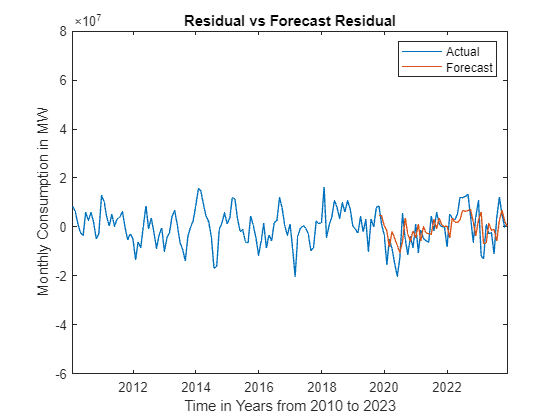

training_portion =0.7;
train_portion_length = round((size(residual,1))*training_portion);
test_portion_length = (size(residual,1)) - train_portion_length;
ARIMA_residual = arima('Constant',NaN,'ARLags',1:1,'D',0,'MALags',1:1,'Distribution','Gaussian');
ARIMA_residual = estimate(ARIMA_residual,residual(1:train_portion_length),'Display','off');
predicted_residual_values = [];
for i = 1: test_portion_length 
    predicted_residual_values = [ predicted_residual_values ; forecast(ARIMA_residual,1,residual(1:train_portion_length+i-1));];
end
% ARIMA_residual = infer(ARIMA_residual,residual(1:test_portion_length));
plot(Date_time,residual)
ylim([-6e+7 8e+7])
xlabel("Time in Years from 2010 to 2023")
ylabel("Monthly Consumption in MW")
title("Residual vs Forecast Residual")
hold on
plot(Date_time(train_portion_length+1:end),predicted_residual_values)
hold off
legend(["Actual" "Forecast"])

#### Error Values for Residual Forecast

error = residual(train_portion_length+1:end) - predicted_residual_values;
absolute_error = abs(error);
bias = mean(error);
MAE = mean(absolute_error);
MAPE = 100 * mean(absolute_error./abs(residual(train_portion_length+1:end)));
fprintf("Error Values for Residual Forecast\nBIAS:%12.2fMW\nMAE: %12.2fMW\nMAPE:%12.2f%%",bias,MAE,MAPE);

Error Values for Residual Forecast
BIAS:  -843919.45MW
MAE:   5986665.11MW
MAPE:      431.99%

#### Forecast Time Series Plotting (Forecast Residual + Trend + Seasonality)

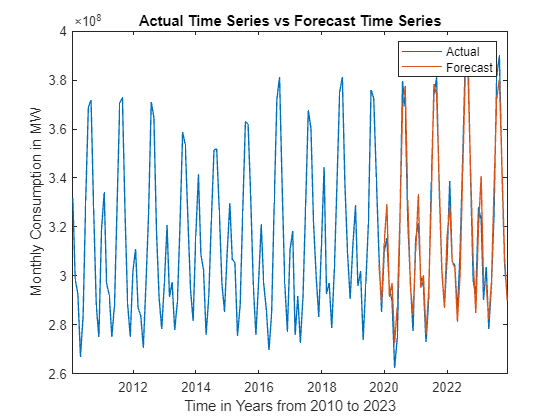

plot(Date_time,actual_time_series)
predicted_time_series = trend((train_portion_length+1:end)) + seasonality_component_complete(train_portion_length+1:end) + predicted_residual_values;
hold on
    plot(Date_time(train_portion_length+1:end), predicted_time_series)
hold off
xlabel("Time in Years from 2010 to 2023")
ylabel("Monthly Consumption in MW")
title("Actual Time Series vs Forecast Time Series")
legend(["Actual" "Forecast"])

#### Error Values for the Timeseries Forecast

error = actual_time_series(train_portion_length+1:end) - predicted_time_series;
absolute_error = abs(error);
bias = mean(error);
MAE = mean(absolute_error);
MAPE = 100 * mean(absolute_error./abs(actual_time_series(train_portion_length+1:end)));
fprintf("Error Values for The Timeseries Forecast\nBIAS:%12.2fMW\nMAE: %12.2fMW\nMAPE:%12.2f%%",bias,MAE,MAPE);

Error Values for The Timeseries Forecast
BIAS:  -843919.45MW
MAE:   5986665.11MW
MAPE:        1.88%